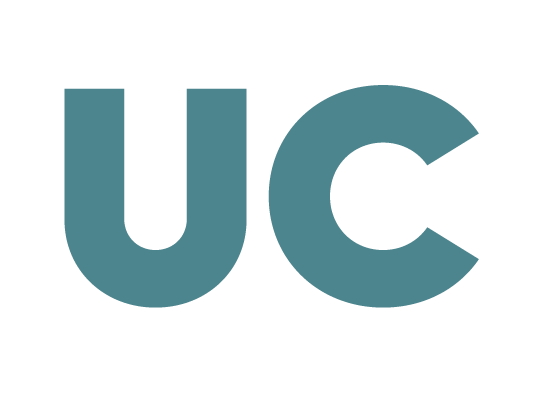

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometría**

# **Práctica 12: Diagonalización**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Cálculo de autovalores y autovectores

- Diagonalización

**Cálculo de autovalores y autovectores**

Imaginemos que tenemos el siguiente endomorfismo:


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^3 \\
(x,y,z) \leadsto (3x-3z, 3y+9z, -3z) $$


Comenzaremos por definir la matriz asociada a $f$ en la base canónica (matriz estándar):

A = [3 0 -3; 0 3 9; 0 0 -3];  % matriz estándar de f

Para hallar los autovalores de $f$ (o $A$), podemos recurrir a la función *eig*:

autoval = eig(A)

Vemos que $f$ tiene como autovalores $\lambda=3$ (doble) y $\lambda=-3$ (simple). El siguiente paso sería calcular los subespacios propios asociados a estos autovalores, para lo cual tendremos que resolver el sistema homogéneo con matriz de coeficientes $A-\lambda_{i} I$, donde $\lambda_i = \lbrace 3, -3 \rbrace$. La solución a este sistema será directamente una base del subespacio propio asociado a $\lambda_i$:

% Subespacio propio asociado al autovalor 3 
baseV3 = null(A - autoval(1)*eye(3), 'r')  % dim(V3)=2=m(3)
% Subespacio propio asociado al autovalor -3 
baseVmenos3 = null(A - autoval(3)*eye(3), 'r')  % dim(Vmenos3)=1=m(-3)

**Diagonalización**

Para que un endomorfismo en un espacio vectorial real sea diagonalizable han de cumplirse dos condiciones:

- Todas las raíces del polinomio característico tienen que ser reales, lo que equivale en MATLAB a que al obtener los autovalores mediante la función eig() no nos de ningún valor complejo.

- La dimensión de cada subespacio propio tiene que coincidir con la multiplicidad (algebraica) del autovalor al que está asociado

En nuestro ejemplo, podemos ver que estos dos puntos se cumplen. Por tanto, $f$ será diagonalizable. Como ya sabemos, diagonalizar $f$ consiste en encontrar una matriz diagonal $D$ y otra $P$ tales que $A=PDP^{-1}$. La diagonal de $D$ estará formada por los autovalores de $f$ y $P$ contendrá en sus columnas una base de autovectores de $f$ del espacio en el que estemos trabajando, en este caso $\mathbb{R}^3$. Como sabes, ha de respetarse el mismo orden al colocar los valores propios en la diagonal de $D$ y los correspondientes vectores propios en las columnas de $P$.

D = diag(autoval)
P = [baseV3 baseVmenos3]

Podemos comprobar fácilmente que, efectivamente, la unión de las bases de los subespacios propios encontrados forman una base (de autovectores de $f$) de $\mathbb{R}^3$:

rank(P)  % los tres vectores son L.I. -> forman base de R³

La comprobación de que las matrices $D$ y $P$ que hemos obtenido son las correctas sería la siguiente:

A - P*D*inv(P)

Otra comprobación equivalente en la que evitamos el cálculo de inversas (muy conveniente para el tratamiento de problemas "a mano") sería la siguiente:

A*P - P*D

Además de los autovalores del endomorfismo, la función *eig *permite también hallar sus autovectores asociados del siguente modo:

[P2, D2] = eig(A)

La matriz $D2$ es la $D$ que habíamos obtenido anteriormente, es decir, la matriz que contiene en su diagonal los autovalores de $A$. Por su parte, $P2$ es una matriz cuyas columnas están formadas por autovectores de $A$ (lógicamente, la primera/segunda/tercera columna de $P2$ corresponde al autovector asociado al autovalor que se sitúa en la primera/segunda/tercera columna de $D2$). Sin embargo, fíjate que esta matriz $P2$ no coincide con la $P$ que habíamos obtenido anteriormente. La única diferencia es que la base que devuelve la función *eig *para cada subespacio propio es una base ortonormal (vectores ortogonales entre sí y unitarios). El mismo resultado obtenido con *eig* lo obtendríamos si elimináramos de *null* la opción 'r' .

% La base devuelta por "eig" para el subespacio propio asociado al 
% autovalor 3 es ortonormal:
dot(P2(:,1), P2(:,2))  % vectores ortogonales
norm(P2(:,1))  % norma 1
norm(P2(:,2))  % norma 1
% En el caso del subespacio propio asociado al autovalor -3, dado que sólo
% tenemos un vector, dicho vector será unitario
norm(P2(:,3))  % norma 1

***Importante*****:** Ten en cuenta que el hecho de que el comando *eig *devuelva dos matrices no implica necesariamente que el endomorfismo con el que se esté trabajando sea diagonalizable. Por ejemplo, imagina que quisiéramos diagonalizar la matriz $A=\left\lbrack \begin{array}{ccc}
2 & 1 & 0\\
0 & 2 & 1\\
0 & 0 & 2
\end{array}\right\rbrack$:

A = [2 1 0; 0 2 1; 0 0 2];  % matriz estándar
[P, D] = eig(A)  % autovalores y autovectores

Aparentemente, ya tendríamos dos matrices $D$ y $P$ necesarias para diagonalizar $A$. Sin embargo, estas matrices no satisfacen la relación $A=PDP^{-1}$:

A - P*D*inv(P)

Y esto ocurre porque $P$ es una matriz singular ($det(P)=0$). En otras palabas, las columnas de $P$ no forman una base de autovectores de $f$, por lo que $A$ no es diagonalizable. En efecto, podemos ver que la dimension del subespacio propio asociado al autovalor $2$ (triple) no coincide con su multiplicidad algebraica.

baseV2 = null(A-2*eye(3), 'r')  % dim(V2)=1, m(2)=3
rank(A-2*eye(3))  % dim(V2) = 3-rg(A-2*I)